# Time domain analysis

%Sampling frequency
fs = 44100

fs = 44100


% Duration of signals
T = 0.5;

%Sine frequency
f = 1000

f = 1000


%Time vector of 0.5s
t = (1/fs:1/fs:T)

t =     0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011



sine_half_second = sin(2*pi*f*t)

sine_half_second =     0.1420    0.2811    0.4145    0.5396    0.6536    0.7545    0.8400    0.9086    0.9587    0.9894    1.0000    0.9904    0.9607    0.9115    0.8439    0.7591    0.6590    0.5455    0.4210    0.2879    0.1490    0.0071   -0.1349   -0.2743   -0.4080   -0.5335   -0.6482   -0.7498   -0.8361   -0.9056   -0.9566   -0.9883   -0.9999   -0.9913   -0.9626   -0.9144   -0.8477   -0.7638   -0.6644   -0.5515   -0.4275   -0.2948   -0.1561   -0.0142    0.1279    0.2674    0.4015    0.5275    0.6428    0.7450


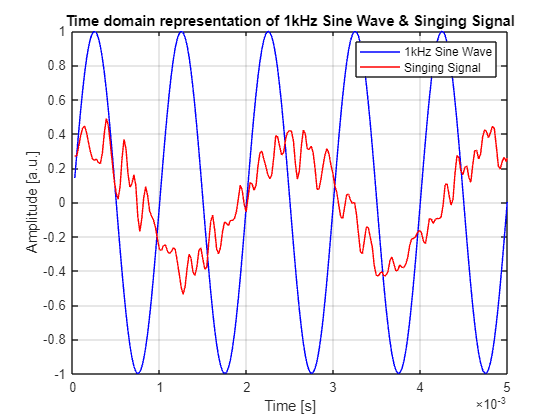


% Load the recording of the singing - make sure Matlab file path is
% configured correctly
[singing, fs_singing] = audioread(['..', filesep, 'Aflevering 1', filesep, ...
                'record_out.wav']); 

% Resample singing signal to match the sine wave sampling rate
singing_resample = resample(singing, fs, fs_singing);


% Number of samples for 0.5 seconds
n_samples = fs * T;  

% Number of samples for 2 seconds - used because singing doesn't start until about 2s have elapsed
n_2s = fs * 2;  

% Extract the 0.5 second segment from the resampled singing signal
singing_half_second = singing_resample(n_2s:n_2s + n_samples - 1);


% Plot both signals on the same plot
figure1 = figure;
plot(t, sine_half_second, '-b');  % Plot sine wave in blue
hold on;
plot(t, singing_half_second, '-r');  % Plot singing signal in red
hold off;

% Add labels, title, and legend
xlim([0 0.005])
xlabel('Time [s]');
ylabel('Amplitude [a.u.]');
title('Time domain representation of 1kHz Sine Wave & Singing Signal');
legend('1kHz Sine Wave', 'Singing Signal');
grid on
hold off

## Frequency analysis


% Fourier transform the signals:
fft_sine = fftshift(fft(sine_half_second));
fft_singing = fftshift(fft(singing_half_second));

% Find magnitude of frequency spectra:
abs_singing = abs(fft_singing);
abs_sine = abs(fft_sine);

%Convert to dB:
abs_singing_dB = 20*log10(abs_singing/max(abs_singing));
abs_sine_dB = 20*log10(abs_sine/max(abs_singing));

length(fft_singing); %Check whether it's odd or not, in order to make frequency vector

% Create frequency vector
Delta_f = (-fs/2+1/T:1/T:fs/2);

% Plot resuslts:
figure2 = figure;
plot(Delta_f, abs_singing_dB, '-r');  % Plot singing signal in red
hold on;
plot(Delta_f, abs_sine_dB, '-b');     % Plot sine signal in blue
xlim([-3000 3000]);                   % Set x-axis limits

title('Frequency Domain Representation of Singing and Sine Signals');
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB], referenced using max of singing signal');
legend('Singing Signal', '1kHz Sine Wave', 'Location','southeast');
grid on;
hold off

% Save figures for assignment
saveas(figure1,'Assignment1_TD','png')

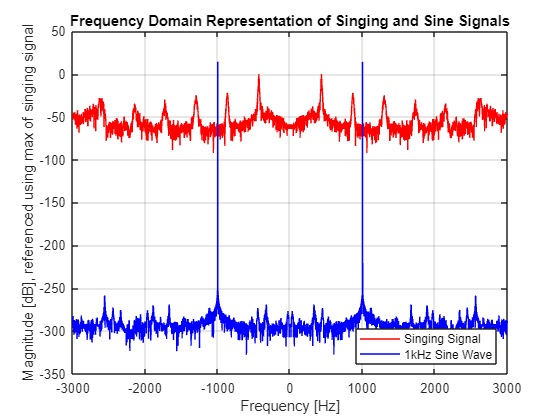

saveas(figure2,'Assignment1_FD', 'png')